syms a b u q w k1 k2 l1 l2 real
syms s complex

A system is described by the two differential equations


$$\frac{dq}{dt}+q-2u+aw = 0$$



$$\frac{dw}{dt}-bq+4u = 0$$


where $q$ and $w$ are functions of time, $u$ is the control input, $q$ is the measured output variable, $a$ and $b$ are constants.

## Convert the above equations into an equivalent state space form


$$\dot{x} = f(x,u) = Ax+Bu$$



$$y = Cx$$


x1 = q;
x2 = w;
x = [x1; x2];
x1dot = -q+2*u-a*w;
x2dot = b*q-4*u;
f = [x1dot; x2dot]

$$f = \left(\begin{array}{c} 2\,u-q-a\,w\\ b\,q-4\,u \end{array}\right)$$

y = q

$$y = q$$

A = jacobian(f,x)

$$A = \left(\begin{array}{cc} -1 & -a\\ b & 0 \end{array}\right)$$

B = jacobian(f,u)

$$B = \left(\begin{array}{c} 2\\ -4 \end{array}\right)$$

C = jacobian(y,x)

$$C = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

D = jacobian(y,u)

$$D = 0$$

## Determine conditions on $a$ and $b$ for which the origin is stable or unstable

pcoeff(a,b) = charpoly(A)  % coefficients of characteristic polynomial

$$pcoeff(a, b) = \left(\begin{array}{ccc} 1 & 1 & a\,b \end{array}\right)$$

eigs(a,b) = eig(A)

$$eigs(a, b) = \left(\begin{array}{c} -\frac{\sqrt{1-4\,a\,b}}{2}-\frac{1}{2}\\ \frac{\sqrt{1-4\,a\,b}}{2}-\frac{1}{2} \end{array}\right)$$

eigs(0,b)

$$ans = \left(\begin{array}{c} -1\\ 0 \end{array}\right)$$

eigs(a,0)

$$ans = \left(\begin{array}{c} -1\\ 0 \end{array}\right)$$

asymptoticallyStableIff = pcoeff > 0

$$asymptoticallyStableIff(a, b) = \left(\begin{array}{ccc} 0<1 & 0<1 & 0<a\,b \end{array}\right)$$

neutrallyStableIff = a*b == 0 % non-repeated eigenvalue on imaginary axis

$$neutrallyStableIff = a\,b=0$$

unstableIff = a*b  < 0

$$unstableIff = a\,b<0$$

### Determine conditions on $a$ and $b$ for which the system is reachable

Wr = [B A*B]

$$Wr = \left(\begin{array}{cc} 2 & 4\,a-2\\ -4 & 2\,b \end{array}\right)$$

detWr = det(Wr)

$$detWr = 16\,a+4\,b-8$$

rankWr = rank(Wr)

rankWr = 2

reachableIff = not(simplify(detWr == 0))

$$reachableIff = 4\,a+b\neq 2$$

## Determine conditions on $a$ and $b$ for which the system is observable

Wo = [C; C*A]

$$Wo = \left(\begin{array}{cc} 1 & 0\\ -1 & -a \end{array}\right)$$

detWo = det(Wo)

$$detWo = -a$$

rankWo = rank(Wo)

rankWo = 2

observableIff = not(simplify(detWo == 0))

$$observableIff = a\neq 0$$

Let us assume the system is reachable and observable

assume(observableIff & reachableIff)
assumptions

$$ans = \left(\begin{array}{cccccccccccccccccccc} K_{f}\in \mathbb{R} & K_{i}\in \mathbb{R} & \alpha \in \mathbb{R} & k\in \mathbb{R} & k_{1}\in \mathbb{R} & k_{2}\in \mathbb{R} & k_{3}\in \mathbb{R} & l_{1}\in \mathbb{R} & l_{2}\in \mathbb{R} & l_{3}\in \mathbb{R} & \omega_{0}\in \mathbb{R} & q\in \mathbb{R} & u\in \mathbb{R} & w\in \mathbb{R} & x_{1}\in \mathbb{R} & x_{2}\in \mathbb{R} & x_{3}\in \mathbb{R} & \zeta \in \mathbb{R} & a\neq 0 & 4\,a+b\neq 2 \end{array}\right)$$

## Use the separation principle to derive the state feedback and observer gains for a dynamic output feedback controller that places all the poles of the closed-loop system at $-1$.

### Compute matrix $K$for a state feedback controller $u=-Kx$ to place e/values of state feedback closed-loop dynamics matrix$A-BK$at desired location

n = length(x) % number of states

n = 2

K = [k1 k2]

$$K = \left(\begin{array}{cc} k_{1} & k_{2} \end{array}\right)$$

ABK = A-B*K

$$ABK = \left(\begin{array}{cc} -2\,k_{1}-1 & -a-2\,k_{2}\\ b+4\,k_{1} & 4\,k_{2} \end{array}\right)$$

pdABK = expand((s-(-1))*(s-(-1))) % desired characteristic polynomial for A-B*K where K is a state feedback

$$pdABK = s^{2}+2\,s+1$$

pABK = det(s*eye(n)-ABK) % actual characteristic polynomial for A-B*K where K is a state feedback

$$pABK = s-4\,k_{2}+a\,b+4\,a\,k_{1}+2\,b\,k_{2}+2\,k_{1}\,s-4\,k_{2}\,s+s^{2}$$

coeffseqr = coeffs(pABK,s) == coeffs(pdABK,s) % equate coefficients

$$coeffseqr = \left(\begin{array}{ccc} a\,b-4\,k_{2}+4\,a\,k_{1}+2\,b\,k_{2}=1 & 2\,k_{1}-4\,k_{2}+1=2 & 1=1 \end{array}\right)$$

Ks = solve(coeffseqr,K,"ReturnConditions",true); % solve for K
Ks.conditions % conditions under which a solution exists

$$ans = \frac{b-2\,a\,b}{4\,a+b-2}\in \mathbb{R}\wedge \frac{2\,a+a\,b-1}{4\,a+b-2}\in \mathbb{R}$$

K = [Ks.k1 Ks.k2] 

$$K = \left(\begin{array}{cc} \frac{b-2\,a\,b}{2\,\left(4\,a+b-2\right)} & -\frac{2\,a+a\,b-1}{2\,\left(4\,a+b-2\right)} \end{array}\right)$$

### Compute observer gain $L$ to place eigenvalues of state estimate error dynamics matrix$A-LC$

L = [l1; l2]

$$L = \left(\begin{array}{c} l_{1}\\ l_{2} \end{array}\right)$$

ALC(L) = A-L*C

$$ALC(l1, l2) = \left(\begin{array}{cc} -l_{1}-1 & -a\\ b-l_{2} & 0 \end{array}\right)$$

pdALC = expand((s-(-1))*(s-(-1)))  % desired characterisic polynomial for observer error dynamics

$$pdALC = s^{2}+2\,s+1$$

pALC = det(s*eye(n)-ALC) % actual characterisic polynomial for observer error dynamics

$$pALC(l1, l2) = s+a\,b-a\,l_{2}+l_{1}\,s+s^{2}$$

coeffseqo = coeffs(pALC,s) == coeffs(pdALC,s) % equate coefficients

$$coeffseqo(l1, l2) = \left(\begin{array}{ccc} a\,b-a\,l_{2}=1 & l_{1}+1=2 & 1=1 \end{array}\right)$$

Ls = solve(coeffseqo,L,"ReturnConditions",true); % solve for L
Ls.conditions % conditions under which a solution exists

$$ans = \frac{a\,b-1}{a}\in \mathbb{R}$$

L = [Ls.l1; Ls.l2]

$$L = \left(\begin{array}{c} 1\\ \frac{a\,b-1}{a} \end{array}\right)$$

## **Compute expression for **observer-based controller

Suppose $a=b=1$. 

Compute a state space expression for an observer-based controller that has as its inputs $y$ and $r$ and 


$$u=-K\hat{x}+K_fr$$
 

as its output, where $r$ is a given constant reference signal and $\hat{x}$ is an estimate of the state. 

A = subs(A,[a, b],[1, 1])

$$A = \left(\begin{array}{cc} -1 & -1\\ 1 & 0 \end{array}\right)$$

K = subs(K,[a, b],[1, 1])

$$K = \left(\begin{array}{cc} -\frac{1}{6} & -\frac{1}{3} \end{array}\right)$$

L = subs(L,[a, b],[1, 1])

$$L = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

Compute the feedforward gain $K_f$ such that $\lim_{t\rightarrow \infty } y(t) = r$.

p = size(C,1) % number of measured outputs

p = 1

Kf = -(C*((A-B*K)\B))\eye(p)

$$Kf = \frac{1}{4}$$

% ALC = A - L*C
% ABK = A - B*K

m = size(B,2); % number of control inputs
Acontrol = A-B*K-L*C;
Bcontrol = [L B*Kf];
Ccontrol = -K;
Dcontrol = [zeros(m,p) Kf];

controller  = ss(eval(Acontrol), eval(Bcontrol), eval(Ccontrol), eval(Dcontrol),'InputName',{'y','r'}','OutputName','u','StateName',{'xhat1', 'xhat2'})

controller =
 
  A = 
            xhat1    xhat2
   xhat1   -1.667  -0.3333
   xhat2   0.3333   -1.333
 
  B = 
            y    r
   xhat1    1  0.5
   xhat2    0   -1
 
  C = 
       xhat1   xhat2
   u  0.1667  0.3333
 
  D = 
         y     r
   u     0  0.25
 
Continuous-time state-space model.



### Check that eigenvalues of closed-loop dynamics matrix are as desired

Closed-loop dynamics matrix with augmented state as$(x,\hat{x})$:

Aclxandxhat = [A -B*K; L*C A-B*K-L*C] 

$$Aclxandxhat = \left(\begin{array}{cccc} -1 & -1 & \frac{1}{3} & \frac{2}{3}\\ 1 & 0 & -\frac{2}{3} & -\frac{4}{3}\\ 1 & 0 & -\frac{5}{3} & -\frac{1}{3}\\ 0 & 0 & \frac{1}{3} & -\frac{4}{3} \end{array}\right)$$

Closed-loop dynamics matrix with augmented state as$(x,\tilde{x})$, where $\tilde{x}=x-\hat{x}$:

Aclxandxtilde = [A-B*K B*K; zeros(n) A-L*C] % block upper triangular

$$Aclxandxtilde = \left(\begin{array}{cccc} -\frac{2}{3} & -\frac{1}{3} & -\frac{1}{3} & -\frac{2}{3}\\ \frac{1}{3} & -\frac{4}{3} & \frac{2}{3} & \frac{4}{3}\\ 0 & 0 & -2 & -1\\ 0 & 0 & 1 & 0 \end{array}\right)$$

Check whether the eigenvalues of the two matrices above are the same and are all at the desired locations

eig(Aclxandxhat)

$$ans = \left(\begin{array}{c} -1\\ -1\\ -1\\ -1 \end{array}\right)$$

eig(Aclxandxtilde)

$$ans = \left(\begin{array}{c} -1\\ -1\\ -1\\ -1 \end{array}\right)$$

## Explore effect of modelling error

meB = 0.9; % modelling error multiplier (me = 1 if no modelling error) try 0.9
meA = 1.1; % modelling error multiplier (me = 1 if no modelling error) try 1.1
process = ss(eval(A*meA), eval(B*meB), eval(C), eval(D),'InputName',{'u'},'OutputName','y','StateName',{'x1', 'x2'})

process =
 
  A = 
         x1    x2
   x1  -1.1  -1.1
   x2   1.1     0
 
  B = 
          u
   x1   1.8
   x2  -3.6
 
  C = 
      x1  x2
   y   1   0
 
  D = 
      u
   y  0
 
Continuous-time state-space model.



clsys = connect(process,controller,'r',{'y', 'u'})

clsys =
 
  A = 
               x1       x2    xhat1    xhat2
   x1        -1.1     -1.1      0.3      0.6
   x2         1.1        0     -0.6     -1.2
   xhat1        1        0   -1.667  -0.3333
   xhat2        0        0   0.3333   -1.333
 
  B = 
             r
   x1     0.45
   x2     -0.9
   xhat1   0.5
   xhat2    -1
 
  C = 
          x1      x2   xhat1   xhat2
   y       1       0       0       0
   u       0       0  0.1667  0.3333
 
  D = 
         r
   y     0
   u  0.25
 
Continuous-time state-space model.



[Acl,Bcl,Ccl,Dcl] = ssdata(clsys);
eig(Acl) % check whether this is the same as above

ans =   -0.8311 + 0.5790i
  -0.8311 - 0.5790i
  -1.3619 + 0.0000i
  -1.0760 + 0.0000i


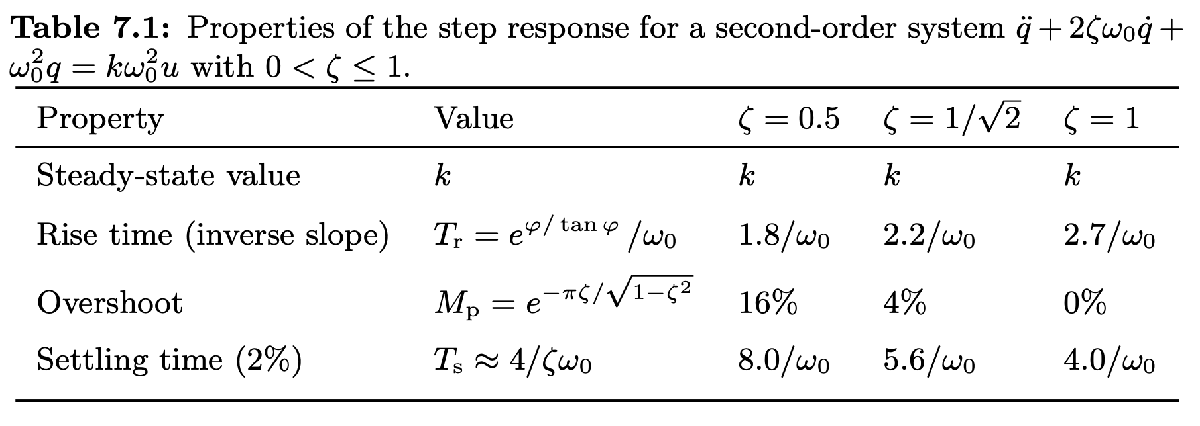

damp(process) % open-loop system

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.50e-01 + 9.53e-01i     5.00e-01       1.10e+00         1.82e+00    
 -5.50e-01 - 9.53e-01i     5.00e-01       1.10e+00         1.82e+00    


damp(clsys) % closed-loop system

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.31e-01 + 5.79e-01i     8.21e-01       1.01e+00         1.20e+00    
 -8.31e-01 - 5.79e-01i     8.21e-01       1.01e+00         1.20e+00    
 -1.08e+00                 1.00e+00       1.08e+00         9.29e-01    
 -1.36e+00                 1.00e+00       1.36e+00         7.34e-01    



stepinfo(process) % open-loop system

ans = struct with fields:
        RiseTime: 1.2501
    SettlingTime: 6.9847
     SettlingMin: 2.9539
     SettlingMax: 3.8978
       Overshoot: 19.1001
      Undershoot: 0
            Peak: 3.8978
        PeakTime: 2.7631


stepinfo(clsys)

ans = 2×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


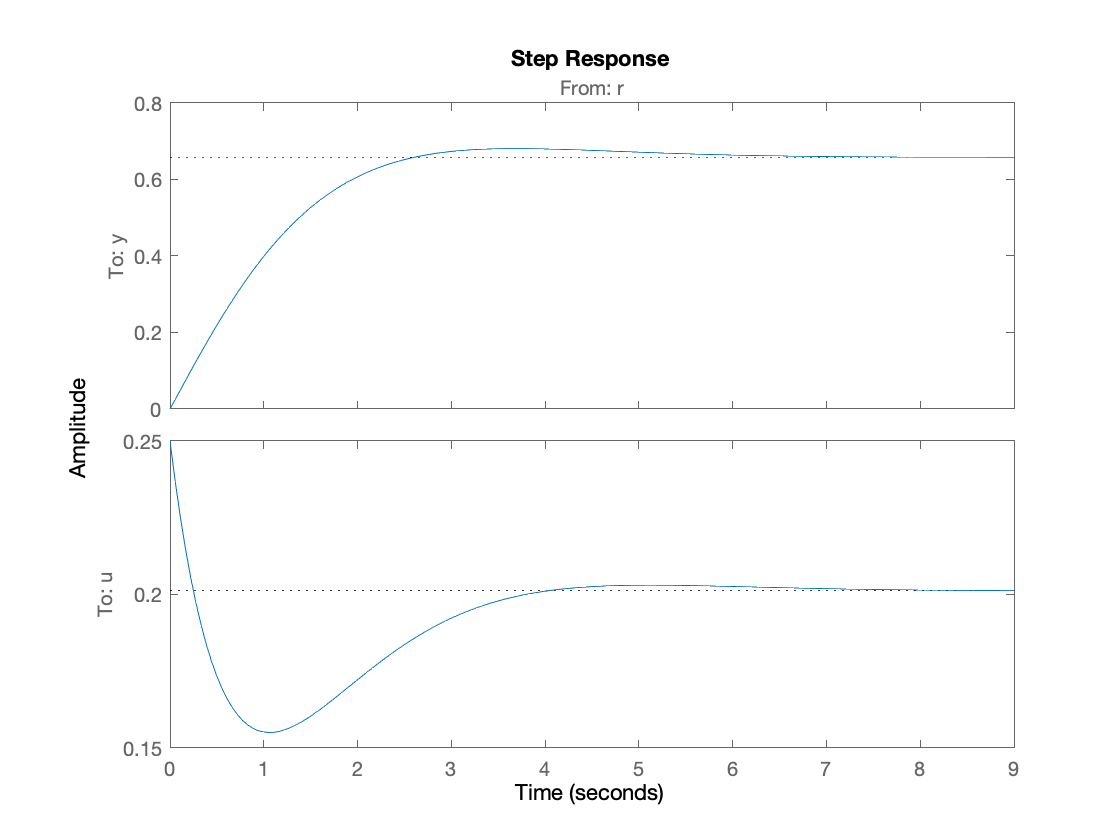

step(clsys)

## Explore effect of error in initial state estimate

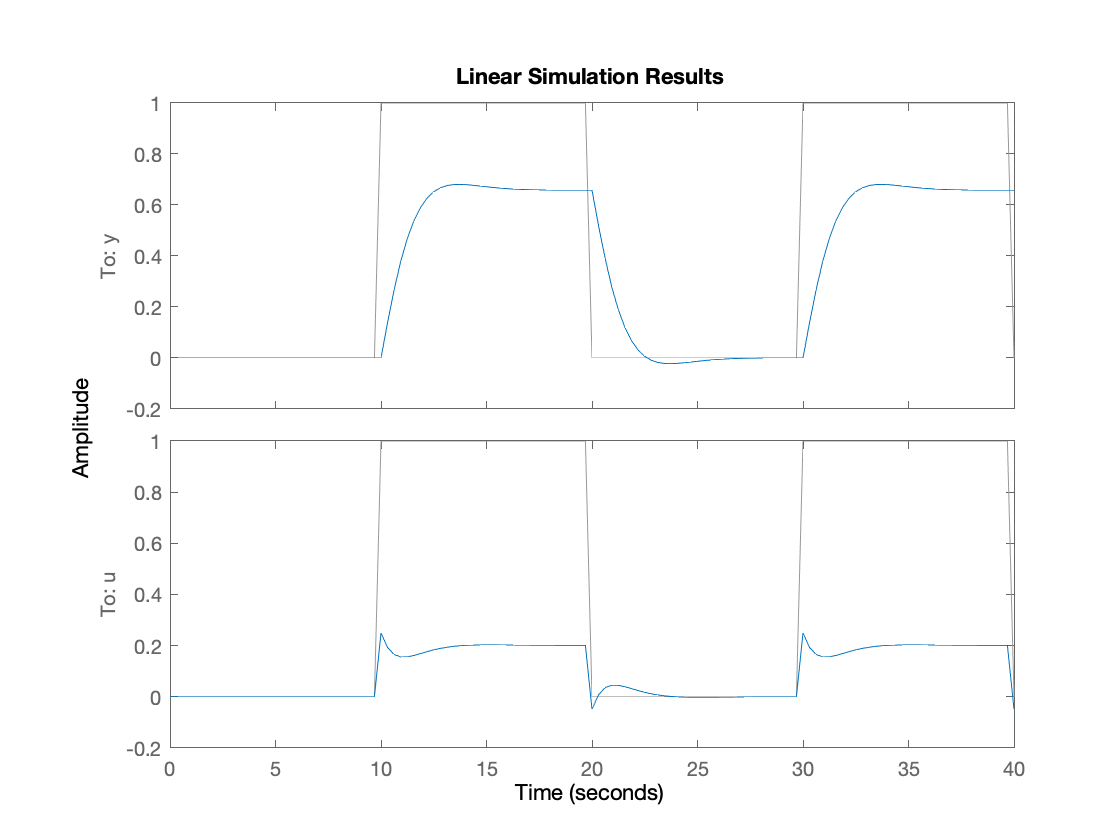

[u,t] = gensig("square",20,40);
x0 = zeros(n,1);
xhat0 = ones(n,1);
lsim(clsys,u,t,[x0; x0]) % no initial state estimate error

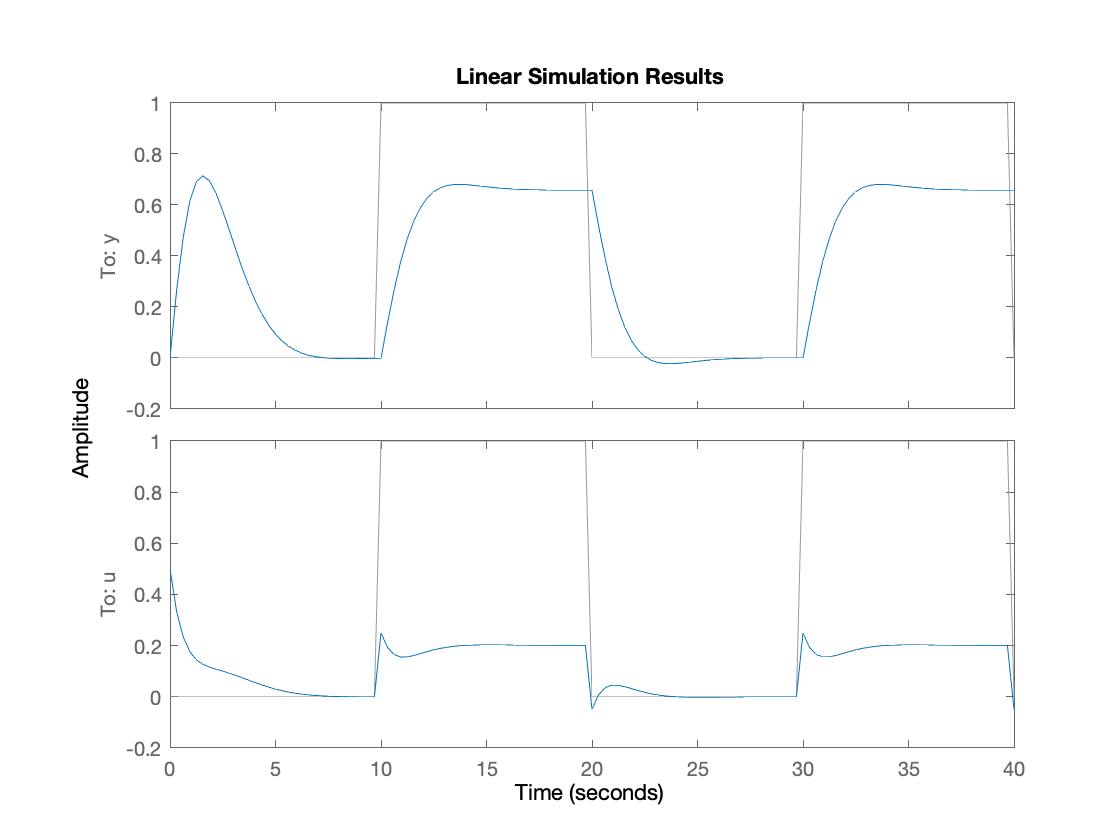

lsim(clsys,u,t,[x0; xhat0]) % initial state estimate error